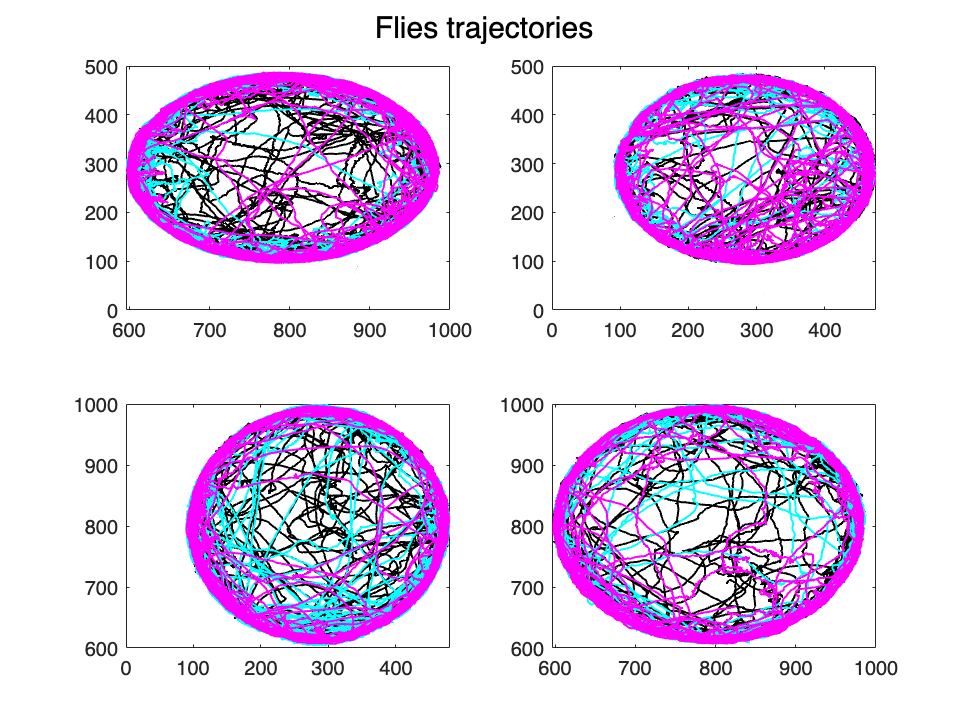

%to use in the fourbubble 2:1 set up
%first on visualizer corretly ID the males 
%load the movie-track.mat on your matlab workspace 
cd ('/Volumes/otopaliklab/flydisco_data/2024-08-15/fourbubble_multibubble__whiteOnly_CS2-1_UASChrimsonVenusX0070_20240815T135729');
load registered_trx.mat
load movie-track.mat

%assign posx and posy
posx=trk.data(:,:,1); %remember to first load the video-track.mat on workspace
posy=trk.data(:,:,2);

%start plotting trajectories
figure;
males_IDs = [1, 4, 7, 10];
females_IDs1 = [2, 5, 8, 11];  % First set of females
females_IDs2 = [3, 6, 9, 12];  % Second set of females

for i = 1:4
    subplot(2, 2, i);  % Create a 2x2 grid of subplots, with the current plot being 'i'
    
    % Plot the chaser's data first
    plot(posx(males_IDs(i), :), posy(males_IDs(i), :), 'k-', 'LineWidth', 1);
    hold on;  % Hold the plot to overlay the next plots on the same subplot
    
    % Plot the first runner's data
    plot(posx(females_IDs1(i), :), posy(females_IDs1(i), :), 'c-', 'LineWidth', 1);
    
    % Plot the second runner's data
    plot(posx(females_IDs2(i), :), posy(females_IDs2(i), :), 'm-', 'LineWidth', 1);

    hold off;  % Release the hold on the current plot

    sgtitle('Flies trajectories')
end

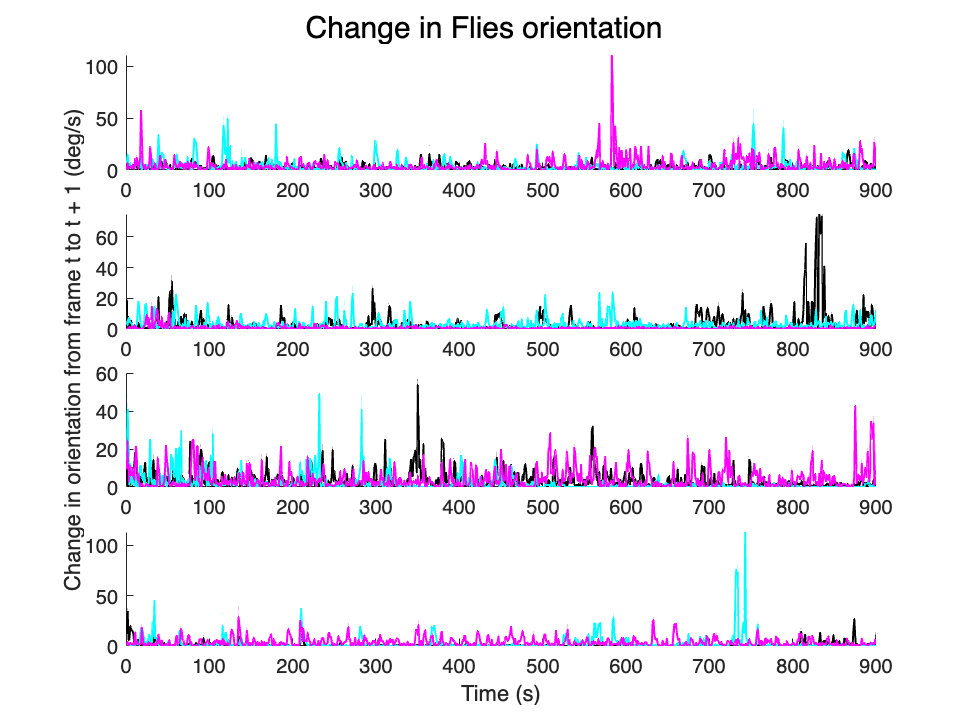


%%%for perframe%%
load ("absdtheta.mat") %load perframe features 
time = trx.timestamps;
new_time = linspace(min(time), max(time), length(data{2}));

% 
% To carry out mean and std, the data has to be numeric or logical
% Therefore, we have to convert cell arrays or structures to numeric array

%to plot a perframe 

figure;
males_IDs = [1, 4, 7, 10];
females_IDs1 = [2, 5, 8, 11];  % First set of females
females_IDs2 = [3, 6, 9, 12];  % Second set of females


for i = 1:4  % Loop over 4 subplots
    subplot(4, 1, i);  % Create a 4x1 grid of subplots
    
    % Plot the chaser's data in black
    plot(data{males_IDs(i)}, 'k-', 'LineWidth', 1);
    hold on;  % Hold on to overlay the next plots
    
    % Plot the first runner's data in blue
    plot(data{females_IDs1(i)}, 'c-', 'LineWidth', 1);
    
    % Plot the second runner's data in red
    plot(data{females_IDs2(i)}, 'm-', 'LineWidth', 1);

    % Set the x-axis limits
    set(gca, 'xlim', [0 900]);
    box off;  % Remove the box around the plot
    hold off;  % Release the hold for the next subplot

    sgtitle('Change in Flies orientation')
han = axes(gcf,'Visible','off');
han.YLabel.Visible = 'on';
% Change ylabel for each parameter
ylabel(han, 'Change in orientation from frame t to t + 1 (deg/s)');
han.XLabel.Visible = 'on';
xlabel(han, 'Time (s)');
end

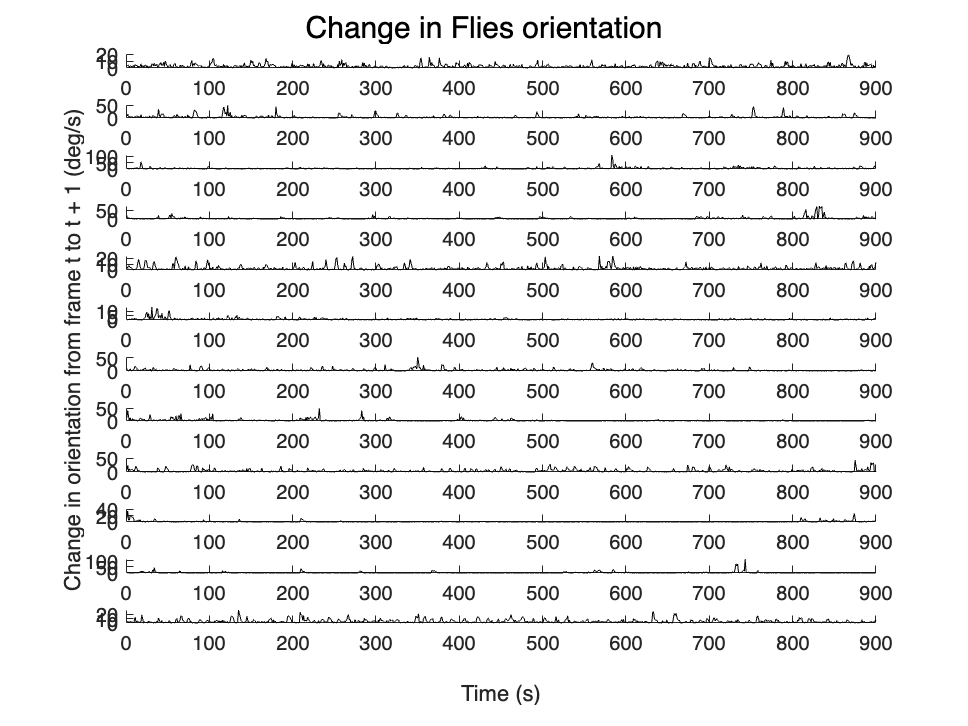


%%%for perframe individual flies
%to plot individual flies perframe
figure;
for i = [ 1 2 3 4 5 6 7 8 9 10 11 12] 
    subplot(12,1,i);
    plot (data {i} , 'k')
    set(gca, 'xlim', [0 900] );
    box off;
    sgtitle('Change in Flies orientation')
han = axes(gcf,'Visible','off');
han.YLabel.Visible = 'on';
% Change ylabel for each parameter
ylabel(han, 'Change in orientation from frame t to t + 1 (deg/s)');
han.XLabel.Visible = 'on';
xlabel(han, 'Time (s)');
end

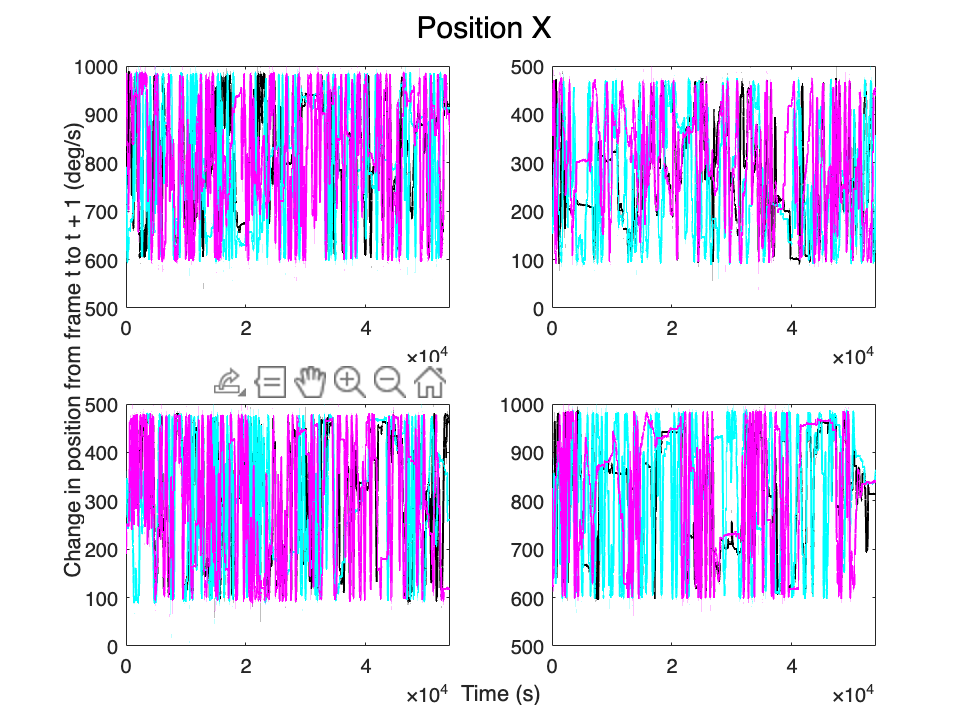


%%%%only posx
figure;
for i = 1:4
    subplot(2, 2, i);  % Create a 2x2 grid of subplots, with the current plot being 'i'
    
    % Plot the chaser's data first
    plot(posx(males_IDs(i), :), 'k-', 'LineWidth', 1);
    hold on;  % Hold the plot to overlay the next plots on the same subplot
    
    % Plot the first runner's data
    plot(posx(females_IDs1(i), :), 'c-', 'LineWidth', 1);
    
    % Plot the second runner's data
    plot(posx(females_IDs2(i), :), 'm-', 'LineWidth', 1);

    hold off;  % Release the hold on the current plot
        % Set the x-axis limits
% axes 
xlim([0 54026])


% Change sgtitle for each parameter
sgtitle('Position X')
han = axes(gcf,'Visible','off');
han.YLabel.Visible = 'on';
% Change ylabel for each parameter
ylabel(han, 'Change in position from frame t to t + 1 (deg/s)');
han.XLabel.Visible = 'on';
xlabel(han, 'Time (s)');
end